# Fixed-Point Implementation of Digital Filters

Dear Students, 

Welcome to Lab 6!

In  the previous lab, you have explored how the pole-zero locations and frequency responses change due to quantization of the coefficients. In this lab, we will implement filters in the digital domain, where both the input data and the filter coefficients are quantized.

### Learning Outcomes: 

At the end of the lab, you will be able to

- Implement a filter using fixed-point representations. 

- Explain about the limit-cycle behaviour of the filters in fixed point implementations. 

### Reference: 

"A.V. Oppenheim and R. W. Schafer, Discrete-Time Signal Processing, Prentice Hall", 2nd or 3rd Edition. 

## IIR Filter Implementation: 

Suppose you want to implement the following filter: $y[n] = ay[n-1]+x[n],\;\forall n\geq 1, y[0] = 0, $using $8$-bit register to store $a, x[n], y[n]$. Let $a = 0.5. $ In the binary notation, $a = 0.100000_2$. However, we cannot store a binary  point in the fixed point register and operate it in a fixed-point processor. Hence, if we store the bits for $a$, **the fixed-point processor sees it as,  **$a = 0100000_2 = 64_{10}.
$ **You as a programmer should remember where the binary point actually is. **In the above case, you as a programmer know that the decimal number represented by the register is actually, $\frac{64}{2^7} = 0.5, $ as the binary point has to be shifted towards right by $7$ places. 

In Matlab, what an 8-bit fixed-point register sees can be represented using the *integer* data types (see [https://in.mathworks.com/help/matlab/matlab_prog/integers.html)](https://in.mathworks.com/help/matlab/matlab_prog/integers.html))

Now, consider the following $a$ vector. 

If you store this in an 8-bit fixed-point register, what values will a fixed-point processor see? Here is the answer. 

 %% Answer
 a  = 0:0.001:1

a =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


 ValuesSeenbyComputer = int8(a*2^7)

ValuesSeenbyComputer = 1×1001 int8 row vector
   0   0   0   0   1   1   1   1   1   1   1   1   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   3   4   4   4   4   4   4   4   4   5   5   5   5   5   5   5   6   6   6   6   6   6   6


In the above, we are manually doing what a fixed-point processor would have done, i.e., shifting the binary point by 7 locations to the right.  (Note that since the processor we are using is not a fixed point processor  and we can represent the floating point numbers given by $a$ directly. However, for the learning purpose, we are trying to imitate what a fixed-point processor would have done). 

Let us now create a signal, named $x[n]$,  which will act an the input to our filter. Please do not worry as to how the below $x[n]$ is generated. 

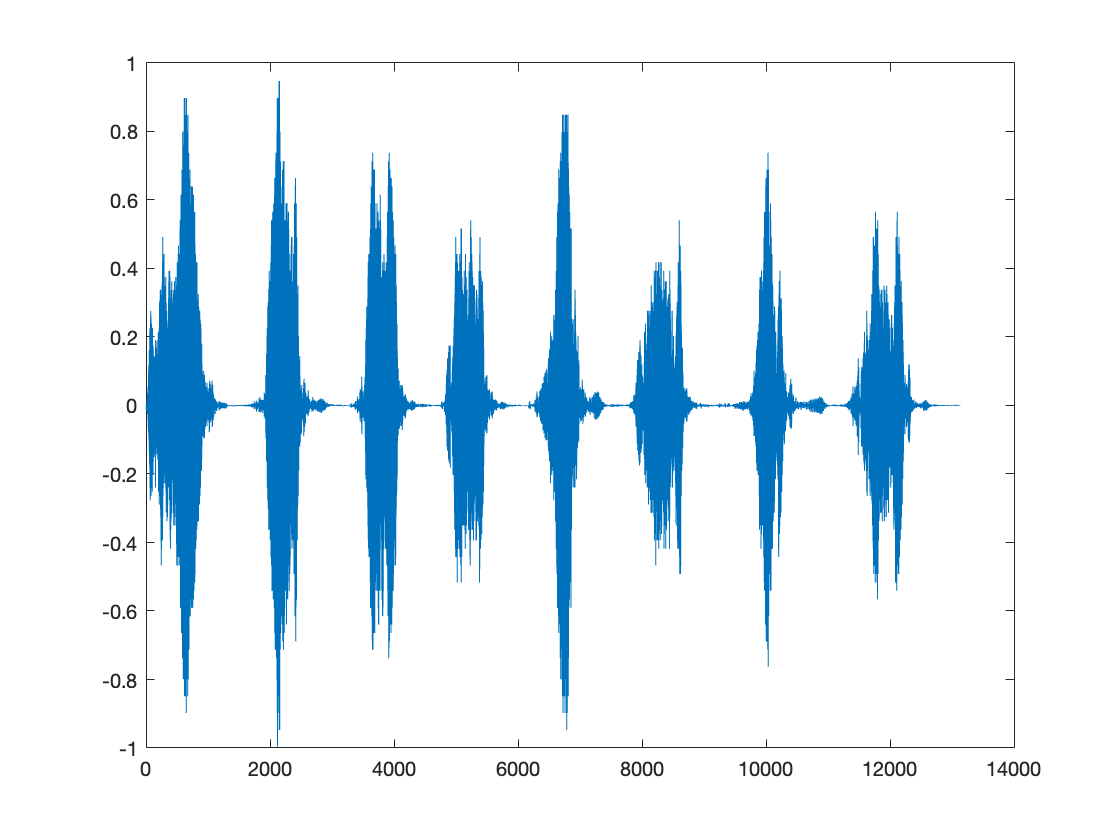

load chirp.mat % It stores the output in y and Fs gives the sampling frequency. 
%sound(y, Fs)  % If required, you can play the sound. 
x = y + 0.2*randn(length(y),1); % We have corrupted it with a Gaussian noise;
x =  x/(max(x)+0.0001); % gaurantee that the input is less than 1. 
plot(y); % Original Signal

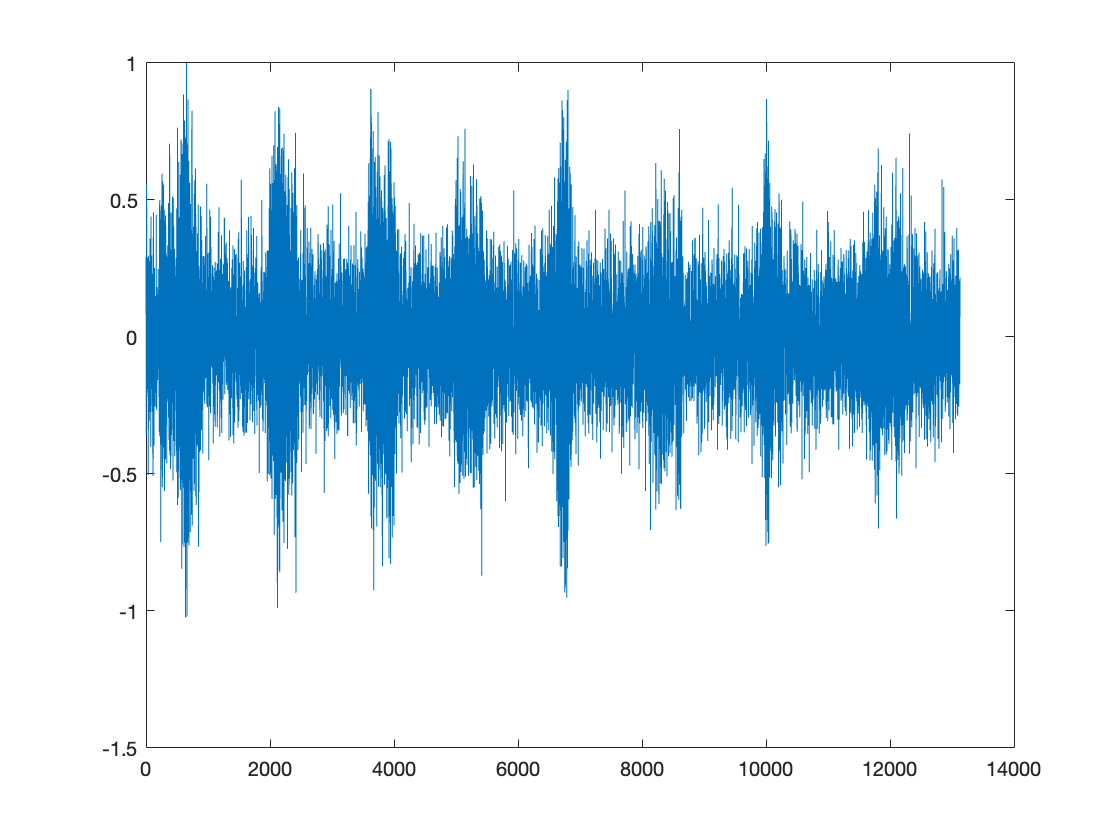

plot(x); % Corrupted Signal, which will act as the input. 

%sound(x, Fs)

### Question (60 Points): 

 In the below, filter *x, *with $y[n] = ay[n-1]+x[n],\;\forall n\geq 2, y[1] = 0, $ using 8-bit registers for storing $a, x[n], y[n]$ and product $ay[n-1]$. 

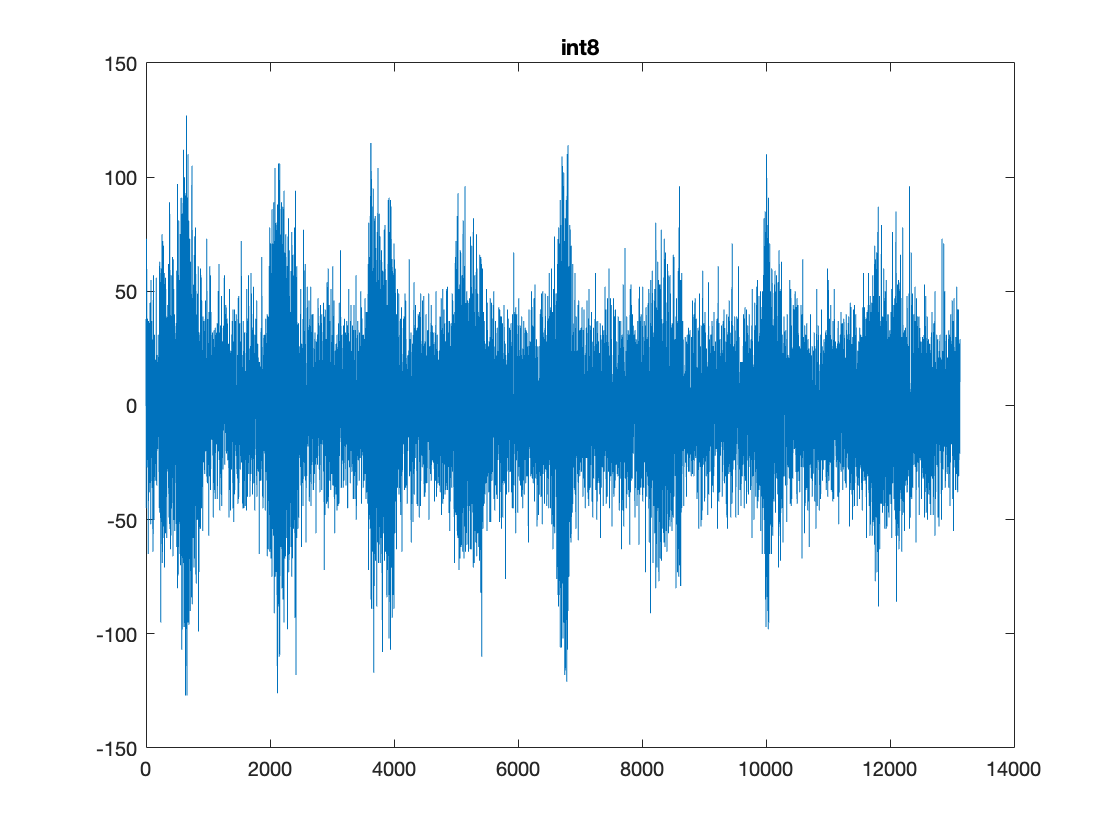

aFixedPoint = int8(0.5*2^7); % the value of a=0.5 seen by a 8-bit fixed point processor. 
xFixedPoint =  int8(x*2^7); % FILL IN THE BLANKS. The values of x seen by a 8-bit fixed point processor. 
FilterOutput(1) =  0; % The output, y[n], of the filter. 

for i = 2: length(xFixedPoint)
    
    FilterOutput(i) =  aFixedPoint * FilterOutput(i-1)/2^7 + xFixedPoint(i);  % FILL IN THE BLANKS. Implement y[n] = ay[n-1]+x[n] here. 
                                                                        % Your output of the multiplier must be represented in the 8-bit fixed-point representation
                                                                        % Your summation must also be done using 8-bit fixed-point arithmetic.   
                                                                        % Pay special attention to what happens when to the binary point location when
                                                                        % you multiply. 
end

Now, perform the above filtering using 16-bit registers. 

aFixedPoint = int16(0.5*2^15); % the value of a=0.5 seen by a 16-bit fixed point processor. 
xFixedPoint =  int16(x*2^15); % FILL IN THE BLANKS the values of x seen by a 16-bit fixed point processor. 
FilterOutput1(1) =  0; % the output, y[n], of the filter. 

for i = 2: length(xFixedPoint)
    
    FilterOutput1(i) =  aFixedPoint * FilterOutput1(i-1)/2^15 + xFixedPoint(i);
    
end

Now, perform the above filtering using 32-bit registers. 

aFixedPoint = int32(0.5*2^31); % the value of a=0.5 seen by a 32-bit fixed point processor. 
xFixedPoint =  int32(x*2^31); % FILL IN THE BLANKS the values of x seen by a 32-bit fixed point processor. 
FilterOutput2(1) = 0; % the output, y[n], of the filter. 

for i = 2: length(xFixedPoint)
    
    FilterOutput2(i) =  aFixedPoint * FilterOutput2(i-1)/2^15 + xFixedPoint(i);   
end

#### Answer the following: 

Observe the ouputs in the above 3 cases and make your comments (this is somewhat a open-ended question. You can decide what you want to comment on). 

*ANSWER: *We observe a better precision and low information loss when we use higher number of bits to represent the fractional part of the numbers. So, 8 bit representation is the least precise and the 32 bit representation is the most precise. Although we use only 15 bits to represent the fractional part even when we have 32 bits to represent the one floating point number, that is because 15 bits provide good enough precision.

## Limit-Cycle Behavior:  

Now, study Example 6.13 in the 2nd Edition of the textbook (or equivalently, Example 6.15 in the 3rd Edition of the textbook). For the example,  we have already written the code:  

### When a = 0.5 using 8-bit Fixed-Point Implementation

y = [];
a =  int8(64);      
x = [0 int8(112) zeros(1,20)];
y(1) = int8(0); 

for i = 2:20
    
    y(i) = a*y(i-1)/2^7 + x(i)
   
end

y =      0   112


y =      0   112     1


y =      0   112     1     1


y =      0   112     1     1     1


y =      0   112     1     1     1     1


y =      0   112     1     1     1     1     1


y =      0   112     1     1     1     1     1     1


y =      0   112     1     1     1     1     1     1     1


y =      0   112     1     1     1     1     1     1     1     1


y =      0   112     1     1     1     1     1     1     1     1     1


y =      0   112     1     1     1     1     1     1     1     1     1     1


y =      0   112     1     1     1     1     1     1     1     1     1     1     1


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


### When a =  - 0.5 using 8-bit Fixed-Point Implementation

a =  int8(-64);      
x = [0 int8(112) zeros(1,20)];
y(1) = int8(0); 

for i = 2:20
    y(i) = a*y(i-1)/2^7 + x(i)
   
end

y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112    -1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112    -1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112    -1     1    -1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112    -1     1    -1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112    -1     1    -1     1    -1     1     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112    -1     1    -1     1    -1     1     1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112    -1     1    -1     1    -1     1    -1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112    -1     1    -1     1    -1     1    -1     1     1     1     1     1     1     1     1     1     1     1


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1     1     1     1     1     1     1     1     1


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1     1     1     1     1     1     1     1     1


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1     1     1     1     1     1     1


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1     1     1     1     1     1     1


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1     1     1     1     1


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1     1     1     1     1


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1     1     1


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1     1     1


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1


### Question (40 Points): 

Now study the above codes and their outputs and make your comments, especially on the following points. 

- What is the limit cycle behavior? Why does it occur? 

- How can we avoid limit cycles? 

- Any other comments? 

*ANSWER: *Limit cycle behavior is the saturation of the output variable in case of an IIR system working with a finite time input (x). In the case we studied, the output saturates to 1 (for a = 0.5) or alternates between -1 and 1 (for a = -0.5). We see this because the small values at the output are getting represented as the least value which is possible to represent using our 8 bit registers ($2^{-7}$). 

We can scale the input signal according to our register size to avoid limit cycles.

**This is the final lab for the semester. Thank you very much for your time, attention and hardwork during the entire semester, both for the theory and the lab parts. It was a great experience working with you. All the best! **

## An Important Question: 

#### Please give your feedback for the lab part of the course if any:  

This lab encouraged us to do more exploring, but I felt we needed more instruction.

As many of the topics in this lab course were new and not introduced to us in the theory part of the course.

Apart from that conduction and grading of this course were very good.

---------------------------------------------------------------------------------------------------------------------------------